syms x(t) theta1(t) theta2(t)
syms l1 l2 c m xPrime0 theta01 theta02 p

deriv's

Dx = diff(x); D2x = diff(x,2);
Dtheta1 = diff(theta1); D2theta1 = diff(theta1,2);
Dtheta2 = diff(theta2); D2theta2 = diff(theta2,2);

Eq of motion:

eq1 = D2theta1 + (D2x/l1)*cos(theta1) + (9.8/l1)*sin(theta1) + (c/m)*Dtheta1 == 0

$$eq1(t) = \frac{49\,\sin\left(\theta_{1}\left(t\right)\right)}{5\,l_{1}}+\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+\frac{c\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)}{m}+\frac{\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{l_{1}}=0$$

eq2 = D2theta2 + (D2x/l2)*cos(theta2) + (9.8/l2)*sin(theta2) + (c/m)*Dtheta2 == 0

$$eq2(t) = \frac{49\,\sin\left(\theta_{2}\left(t\right)\right)}{5\,l_{2}}+\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)+\frac{c\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)}{m}+\frac{\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{l_{2}}=0$$

eq3 = 2*D2x + ...
      l1*D2theta1*cos(theta1) - l1*Dtheta1^2*sin(theta1) + ...
      l2*D2theta2*cos(theta2) - l2*Dtheta2^2*sin(theta2) == 0

$$eq3(t) = 2\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}-l_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+l_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=0$$

Initial conditions

conds = [x(0) == 0, ...
         Dx(0) == xPrime0, ...
         theta1(0) == theta01, ...
         Dtheta1(0) == 0, ...
         theta2(0) == theta02, ...
         Dtheta2(0) == 0];

Solving

vars = [x; theta1; theta2];
eqs = [eq1; eq2; eq3];

Numeric values

l1 = 1.0;
l2 = 1.2;
m = 1.0;
c = 0.05;
p = 10;
xPrime0 = 0.2;
theta01 = deg2rad(25);
theta02 = deg2rad(-3);

Ode

[V, Y] = odeToVectorField(eqs);
odefun = matlabFunction(V, 'Vars', {'t', 'Y', 'l1', 'l2', 'c', 'm'});

Y0 = [0; xPrime0; theta01; 0; theta02; 0];
tspan = [0 double(p)];

[tSol, YSol] = ode15s(@(t,Y) odefun(t,Y,l1,l2,c,m), tspan, Y0);


Solutions

xSol      = YSol(:,1);
theta1Sol = YSol(:,3);
theta2Sol = YSol(:,5);

Solution at t end

xAnchor = xSol(end);
angle1 = theta1Sol(end);
angle2 = theta2Sol(end);

Position

xBob1 = xAnchor + l1*sin(angle1)

xBob1 = 2.1165

yBob1 = -l1*cos(angle1)

yBob1 = -0.9985

xBob2 = xAnchor + l2*sin(angle2)

xBob2 = 2.2360

yBob2 = -l2*cos(angle2)

yBob2 = -1.1982

visualization

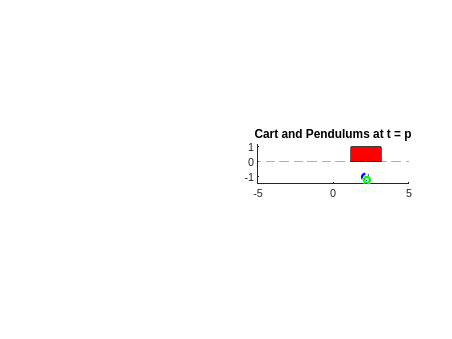

% Geometry for plotting
cartWidth = 2;
cartHeight = 1;
bobRadius = 0.2;

subplot(1,2,2)
hold on; axis equal
xlim([-5 5])
ylim([-max([l1,l2])*1.2 1.2])

% Ground
line([-10 10], [0 0], 'Color', [0.5 0.5 0.5], 'LineStyle', '--');

% Cart
rectangle('Position',[xAnchor - cartWidth/2, 0, cartWidth, cartHeight], ...
          'FaceColor','r', 'EdgeColor','k');

% Pendulum 1
line([xAnchor xBob1], [0 yBob1], 'Color','w', 'LineWidth',2);
viscircles([xBob1 yBob1], bobRadius,'Color','blue');

% Pendulum 2
line([xAnchor xBob2], [0 yBob2], 'Color','w', 'LineWidth',2);
viscircles([xBob2 yBob2], bobRadius,'Color','green');

title('Cart and Pendulums at t = p');

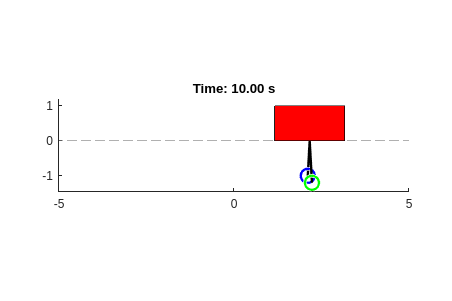


figure('Position',[100 100 600 400])
for k = 1:1:length(tSol)
    clf;
    xAnchor = YSol(k,1);
    theta1f = YSol(k,3);
    theta2f = YSol(k,5);

    xBob1 = xAnchor + l1 * sin(theta1f);
    yBob1 = -l1 * cos(theta1f);
    xBob2 = xAnchor + l2 * sin(theta2f);
    yBob2 = -l2 * cos(theta2f);

    hold on; axis equal
    xlim([-5 5])
    ylim([-max([l1,l2])*1.2 1.2])

    % Ground
    line([-10 10], [0 0], 'Color', [0.5 0.5 0.5], 'LineStyle', '--');

    % Cart
    rectangle('Position',[xAnchor - cartWidth/2, 0, cartWidth, cartHeight], ...
              'FaceColor','r', 'EdgeColor','k');

    % Pendulums
    line([xAnchor xBob1], [0 yBob1], 'Color','k', 'LineWidth',2);
    viscircles([xBob1 yBob1], bobRadius,'Color','blue');

    line([xAnchor xBob2], [0 yBob2], 'Color','k', 'LineWidth',2);
    viscircles([xBob2 yBob2], bobRadius,'Color','green');

    title(sprintf('Time: %.2f s', tSol(k)));
    pause(0.03);
end